# Explore the challenge dataset

Use this to store the root location where you saved the downloaded dataset

dataloc = 'C:\Users\nidul\Desktop\ACCA Folder My\Signal processing cup\ROBOVOX_SP_CUP_2024';
cd(dataloc)

## Enroll data

The essential data to use for the challenge is all included within the "single-channel" subfolder

singleChLoc = fullfile(dataloc,'single-channel');

Let's look at the dimensions of the enrollment data first

enrollloc = fullfile(singleChLoc,'enrollment');

The speaker tag is included in the name of the audio recording files, as the string that precedes the first "-"

%spk_labels_enroll = filenames2labels(enrollloc,ExtractBefore="-",FileExtensions=".wav");

How many unique speaker tags can we count?

spk_ids = unique(spk_labels_enroll)
numSpk = height(spk_ids)

How many enrollment files per speaker?

numfiles_enroll = zeros(numSpk,1);
for kSpk = 1:numSpk
    numfiles_enroll(kSpk) = sum(double(spk_labels_enroll == spk_ids(kSpk)));
end
spkFileCount_enroll = table(spk_ids,numfiles_enroll)

Read a few samples

Create a "datastore" object first. Use datastores to:

- Read dataset files sequentially, without having to specify individual file names

- Pair files and labels (other methods also available)

- Pass collections of files to AI models of other built-in functions

- Summarize statistics around dataset

ads_enr = audioDatastore(enrollloc);
%ads_enr.Labels = spk_labels_enroll
countEachLabel(ads_enr)


ans =

  0×0 empty table



shuffle(ads_enr)

ans =   audioDatastore with properties:

                       Files: {
                              ' ...\single-channel\enrollment\spk_47-47_12_0_0_d4_ch5.wav';
                              ' ...\single-channel\enrollment\spk_4-4_10_0_0_d5_ch5.wav';
                              ' ...\single-channel\enrollment\spk_62-62_11_0_0_d2_ch5.wav'
                               ... and 222 more
                              }
                     Folders: {
                              ' ...\Signal processing cup\ROBOVOX_SP_CUP_2024\single-channel\enrollment'
                              }
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
                      Labels: {}
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


Listen to and inspect a few randomly sampled files

[x,xinfo] = read(ads_enr)

x =    -0.0074
   -0.0062
   -0.0047
   -0.0040
    0.0027
    0.0070
    0.0036
   -0.0014
    0.0019
    0.0053


xinfo = struct with fields:
    SampleRate: 16000
      FileName: 'C:\Users\nidul\Desktop\ACCA Folder My\Signal processing cup\ROBOVOX_SP_CUP_2024\single-channel\enrollment\spk_10-10_21_0_0_d2_ch5.wav'


soundsc(x,xinfo.SampleRate)

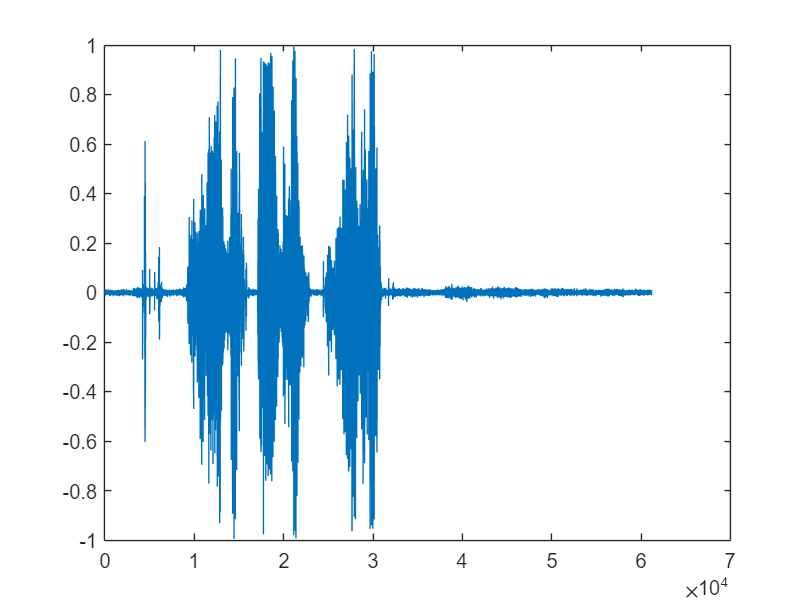

sampleClippedEnrollmentFile = "spk_10-10_21_0_0_d2_ch5.wav";
% sampleClippedEnrollmentFile = "spk_13-13_19_0_1_d1_ch5.wav";
[x,fs] = audioread(fullfile(enrollloc,sampleClippedEnrollmentFile));
plot(x)

Note:

- Important amplitude clipping

- Fairly "generous" segmentation

- High noise floor

soundsc(x,fs)

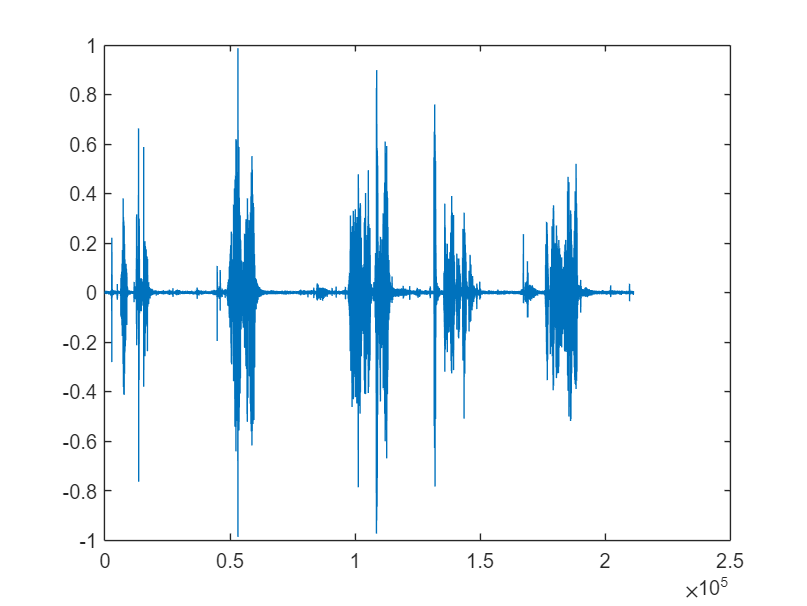

sampleNonsegmentedEnrollmentFile = "spk_15-15_19_0_1_d6_ch5.wav";
[x,fs] = audioread(fullfile(enrollloc,sampleNonsegmentedEnrollmentFile));
plot(x)

soundsc(x,fs)

## Test data

testLoc = fullfile(singleChLoc,'test');
ads_test = audioDatastore(testLoc)

ads_test =   audioDatastore with properties:

                       Files: {
                              ' ...\ROBOVOX_SP_CUP_2024\single-channel\test\0000f88619.wav';
                              ' ...\ROBOVOX_SP_CUP_2024\single-channel\test\000f6d0072.wav';
                              ' ...\ROBOVOX_SP_CUP_2024\single-channel\test\001dd0cb47.wav'
                               ... and 10329 more
                              }
                     Folders: {
                              ' ...\Signal processing cup\ROBOVOX_SP_CUP_2024\single-channel\test'
                              }
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
                      Labels: {}
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


numTestFiles = length(ads_test.Files)

numTestFiles = 10332

shuffle(ads_test)

ans =   audioDatastore with properties:

                       Files: {
                              ' ...\ROBOVOX_SP_CUP_2024\single-channel\test\e1b7d75527.wav';
                              ' ...\ROBOVOX_SP_CUP_2024\single-channel\test\c4e70222f6.wav';
                              ' ...\ROBOVOX_SP_CUP_2024\single-channel\test\64a5bf53c4.wav'
                               ... and 10329 more
                              }
                     Folders: {
                              ' ...\Signal processing cup\ROBOVOX_SP_CUP_2024\single-channel\test'
                              }
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
                      Labels: {}
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


Inspect and listen to test samples

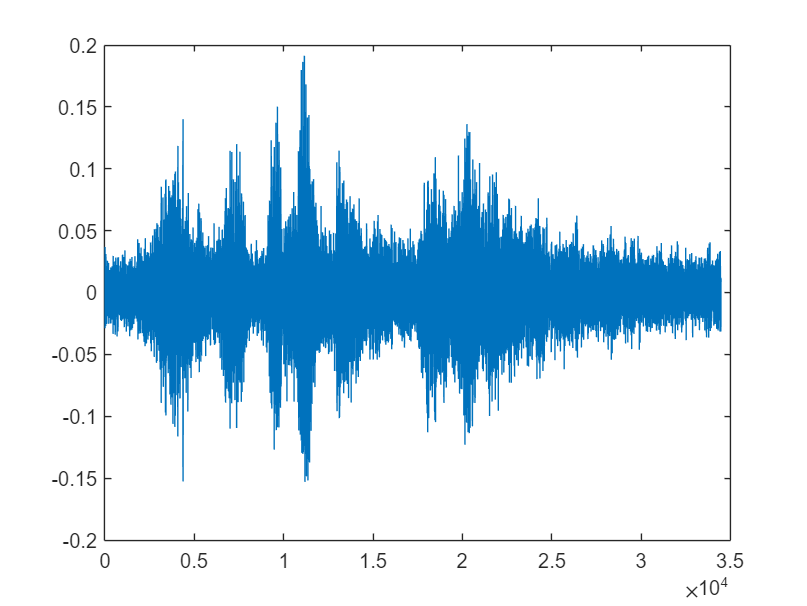

[x,xinfo] = read(ads_test);
plot(x)

soundsc(x,xinfo.SampleRate)

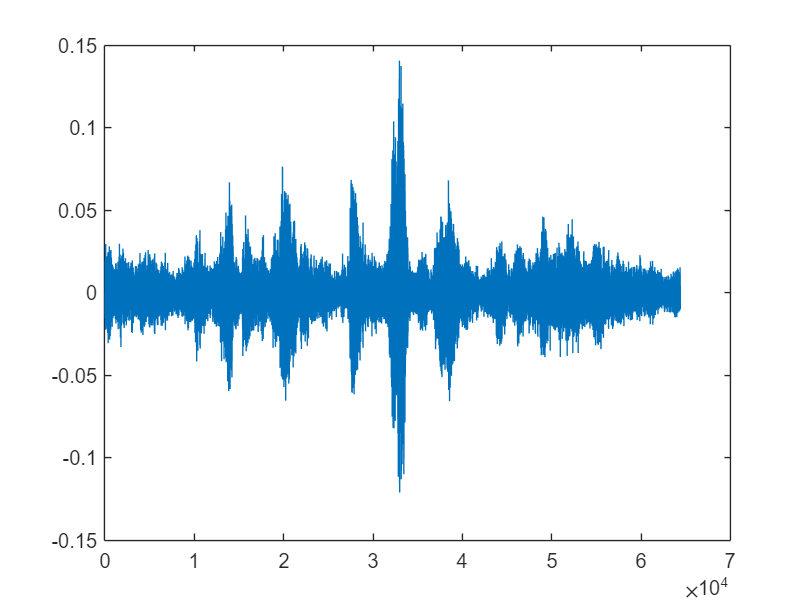

% sampleTestFile = "0000f88619.wav"; % Noise only?
% sampleTestFile = "00465a38b0.wav"; % More than on target speaker
sampleTestFile = "006a19dfc1.wav"; % More than on target speaker
[x,fs] = audioread(fullfile(testLoc,sampleTestFile));
plot(x)

soundsc(x,fs)

Note:

- Even higher noise floor

- Significant reverb

- Additional possible challenges (more than one speaker, no speaker, ...)

## Mandated trials

Inspect trials file

trialsFilename = 'signle-channel-trials.trl';
open(fullfile(singleChLoc,trialsFilename))

Import pairs into table

trialsTable = readtable(fullfile(singleChLoc,trialsFilename), ...
    FileType='text',Delimiter=" ",ReadRowNames=false,ReadVariableNames=false)

trialsTable = 102558×1 table
             Var1         
    ______________________

    {'spk_71→b80bb95d16'}
    {'spk_71→e64da37b33'}
    {'spk_71→c22d8f9d8a'}
    {'spk_71→20e087d5bf'}
    {'spk_71→c5396d4af7'}
    {'spk_71→07e622c018'}
    {'spk_71→70d3397783'}
    {'spk_71→e967199344'}
    {'spk_71→35e670b698'}
    {'spk_71→6d80d0d2a1'}
    {'spk_71→97bbaeadba'}
    {'spk_71→a62faf1119'}
    {'spk_71→34ceda1014'}
    {'spk_71→33e5a6f028'}
    {'spk_71→bf3c182f9a'}
    {'spk_71→e350f7e8d3'}


How many trials requested for scoring?

numTrials = height(trialsTable)

numTrials = 102558

How many possible trials are there?

numPossiblePairs = numSpk * numTestFiles

numPossiblePairs = 774900

How may trials per speaker?

numfiles = zeros(numSpk,1);
for kSpk = 1:numSpk
    numfiles(kSpk) = sum(categorical(trialsTable.Var1) == spk_ids(kSpk));
end
spkFileCount = table(spk_ids,numfiles)

## Additional "Samples" data folder

locraw = fullfile(dataloc,'samples');
rawds = audioDatastore(locraw,'IncludeSubfolders', true)

rawds =   audioDatastore with properties:

                       Files: {
                              ' ...\Signal processing cup\ROBOVOX_SP_CUP_2024\samples\1_1_0_1\sound.wav';
                              ' ...\Signal processing cup\ROBOVOX_SP_CUP_2024\samples\1_1_1_0\sound.wav';
                              ' ...\Signal processing cup\ROBOVOX_SP_CUP_2024\samples\1_22_0_0\sound.wav'
                               ... and 35 more
                              }
                     Folders: {
                              ' ...\ACCA Folder My\Signal processing cup\ROBOVOX_SP_CUP_2024\samples'
                              }
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
                      Labels: {}
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


Inspect one sample

[xs,xsinfo] = read(rawds)

xs =          0         0         0         0         0         0         0         0
    0.0000    0.0001    0.0000    0.0000         0    0.0000         0         0
         0   -0.0000         0         0         0         0         0         0
   -0.0001   -0.0001   -0.0001   -0.0000         0   -0.0001   -0.0000   -0.0000
    0.0002    0.0005    0.0003    0.0002         0    0.0003    0.0001    0.0001
   -0.0004   -0.0011   -0.0005   -0.0003         0   -0.0007   -0.0002   -0.0002
    0.0007    0.0019    0.0008    0.0006    0.0001    0.0012    0.0004    0.0003
   -0.0008   -0.0028   -0.0009   -0.0009   -0.0002   -0.0017   -0.0006   -0.0005
    0.0013    0.0049    0.0013    0.0016    0.0003    0.0031    0.0011    0.0009
    0.0189    0.0416    0.0235    0.0146    0.0010    0.0283    0.0102    0.0081


xsinfo = struct with fields:
    SampleRate: 16000
      FileName: 'C:\Users\nidul\Desktop\ACCA Folder My\Signal processing cup\ROBOVOX_SP_CUP_2024\samples\1_29_0_1\sound.wav'


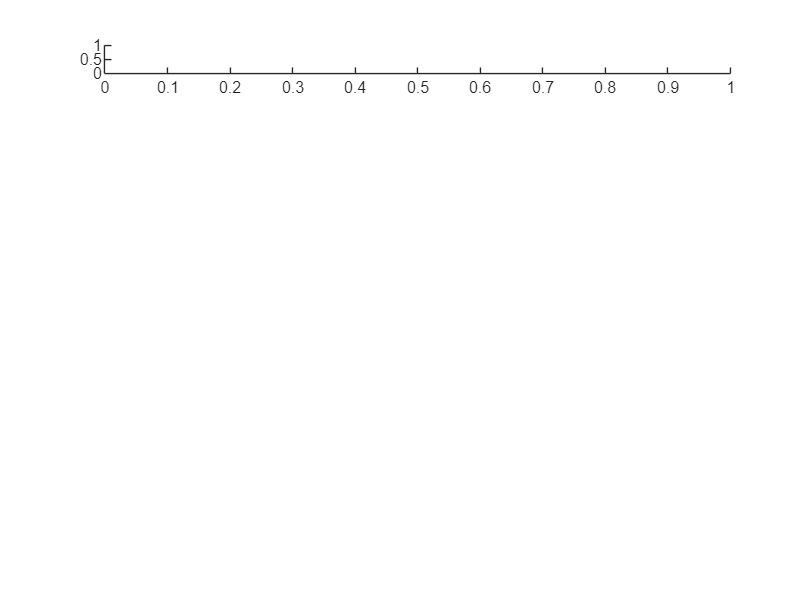

Unrecognized function or variable 'audioEnvelope'.

numch = size(xs,2);
figure
tl = tiledlayout(8,1);
for kc = 1:numch
    nexttile
    % plot(x(:,kc))
    audioEnvelope(xs(:,kc), SampleRate=info.SampleRate)
end

tl.TileSpacing = 'none';
tl.Padding = 'tight';

## Samples Folder - Retrieve Speaker and ROI labels

The speaker ID are easy to get through the folder names

rawlabs = folders2labels(rawds);
spkrlabs = extractBefore(string(rawlabs), "_");

Store anything following the speaker ID in a separate "Run" variable

runlabs = extractAfter(string(rawlabs), "_");

Get ROI - Parse file "annotations.txt" for each recording and store the ROI data in a separate ROI table

Note: start and stop times define regions where *the robot* (not the human speaker) is talking

numruns = height(rawlabs);
roi = cell(numruns,1);
for krun = 1:numruns
    filename = fullfile(locraw,string(rawlabs(krun)),'annotations.txt');
    t = readtable(filename,ReadVariableNames=false,ReadRowNames=true);
    t.Properties.VariableNames = ["start","stop"];
    roi{krun} = t;
end

Example of imported ROI labels for a single multi-channel recording

t

t = 7×2 table
                 start       stop 
                ________    ______

    noise       0.009348    3.0124
    greeting      3.0184    5.1663
    0             7.8933    10.344
    1             12.895    14.792
    2             17.522    19.866
    3             21.805    24.503
    4             27.811    30.347


Collate all labels into a table

anno = table(spkrlabs,runlabs,roi);
anno.Properties.VariableNames = ["Speaker","Run","ROI"];
rawds.Labels = anno;

## Samples Folder - inspect and playback individual channels

[x,info] = read(rawds);
fs = info.SampleRate;

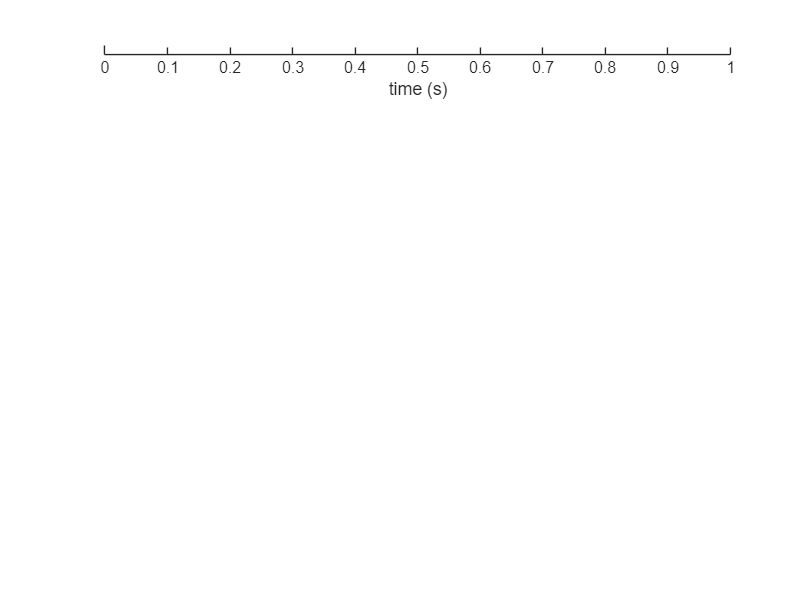

probeChannel = 4;
y = x(:,probeChannel);
t = (1/fs) * (0:length(y)-1)';
xlabel('time (s)')

soundsc(x(:,probeChannel),info.SampleRate);
numch = size(x,2);
% stackedplot(x)
tl = tiledlayout("vertical");

Error using tiledlayout
Invalid arguments.

## Samples Folder - Process and use ROI labels

The original ROI table identify two initial regions commons to all recordings, and a few start+stop "regions of interest" corresponding to the robot questions

roiTime = info.Label.ROI{1}

roiTime = 7×2 table
                 start       stop 
                ________    ______

    noise       0.004176    3.0072
    greeting      3.0195    6.0157
    0             8.8901    10.994
    1             14.182     17.23
    2             19.855    21.408
    3             23.146     25.99
    4             28.081    30.983


roiSamples = round(info.SampleRate * roiTime{:,:})

roiSamples =           67       48116
       48312       96251
      142241      175900
      226907      275681
      317676      342535
      370344      415839
      449289      495730


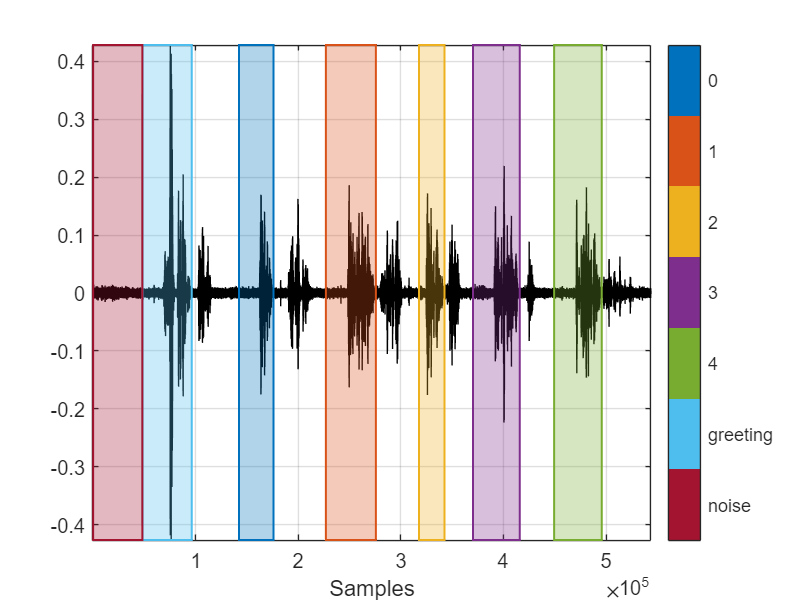

mask = sigroi2binmask(roiSamples);
% sigmask = signalMask(table(roiSamples(2:end,:),repmat("robot",height(roiSamples)-1,1)));
sigmask = signalMask(table(roiSamples(1:end,:),string(roiTime.Properties.RowNames)));
figure
plotsigroi(sigmask,x(:,4),true)

Construct an ROI table identifying the **speaker responses**

auinfo = audioinfo(info.FileName);
spkRoi = [roiSamples(2:end-1,2),roiSamples(3:end,1);...
    roiSamples(end,2), auinfo.TotalSamples]

spkRoi =        96251      142241
      175900      226907
      275681      317676
      342535      370344
      415839      449289
      495730      543744


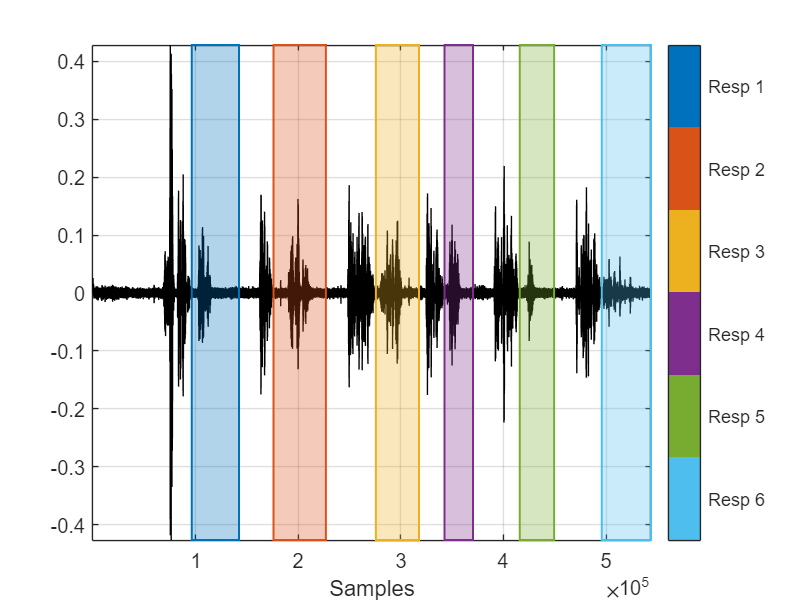

sigmask = signalMask(table(spkRoi,string("Resp " + string(1:height(spkRoi))')));
plotsigroi(sigmask,x(:,4),true)

Y = extractsigroi(y,spkRoi,false)

Y = 6×1 cell array
    {45991×1 double}
    {51008×1 double}
    {41996×1 double}
    {27810×1 double}
    {33451×1 double}
    {48015×1 double}


probeSegment = 6

probeSegment = 6

soundsc(Y{probeSegment},fs)

## Create a few different datastores to help get data of interest

Transform datastore to only get region labeled as "noise" in each recording (initial segment)

noiseds = transform(rawds,@getSampleNoise,IncludeInfo=true); 

Error using nargin
Function getSampleNoise does not exist.

Error in matlab.io.datastore.TransformedDatastore (line 148)
                tFuncArgs = nargin(fun);

Error in matlab

Transform datastore to get robot greeting for each segment - not overly useful, just proof of concept

greetds = transform(rawds,@getSampleGreeting,IncludeInfo=true);

Transform datastore to get individual ordered segments of speaker responses (**only channels 4 and 5!**)

seg3ds = transform(rawds,@getSampleSegment3,IncludeInfo=true);
seg5ds = transform(rawds,@getSampleSegment5,IncludeInfo=true);

Transform datastore to get **all** ordered segments of speaker responses (**only channels 4 and 5!**) - the output is a cell array where each cell is a multi-channel segment with human reponses

segsds = transform(rawds,@getSampleSegments,IncludeInfo=true);
[x,info] = read(segsds); 

Example: get a random noise sample for channel 5 (enrollment channel)

shuffle(noiseds);

[n, ninfo] = read(noiseds);
size(n)
% Channel 1 -> channel 4
% Channel 2 -> channel 5
soundsc(n(:,1),fs)

*Copyright 2023 The MathWorks, Inc.*